clc; clearvars; close all
addpath('reticolo')
addpath('texture functions')
addpath('utils')

## Materials

% Background material
mat_background = "air";
n_background = 1;
note_background = "";

% Pillar material
mat_pillar = "Si";
n_pillar = 3.427;
note_pillar = "Si at 4 um, refractiveindex.info/?shelf=main&book=Si&page=Franta-300K";

% Substrate material
mat_substrate = "Al2O3";
n_substrate = 1.675;
note_substrate = "Al2O3 at 4 um, refractiveindex.info/?shelf=main&book=Al2O3&page=Malitson-o";

## Parameters

pitch = 2;              % μm, meta-atom pitch
height = 2.6;           % μm, meta-atom height

% Pillar Width or Diameter Sampling
num_widths = 50;       % Number of different pillar widths to simulate
min_width = 0.1 * height;  % μm, Minimum pillar width
max_width = 0.7 * pitch;   % μm, Maximum pillar width

% Wavelength Sampling
num_wavelengths = 5;  % Number of different wavelengths to simulate
min_wavelength = 3;    % μm, Minimum wavelength to simulate
max_wavelength = 5;    % μm, Maximum wavelength

pillar_shape = "circle";  % "circle" or "square"
type = "pillars";         % "pillars" or "holes"

if strcmp(pillar_shape, "square")
    corners = "square";
elseif strcmp(pillar_shape, "circle")
    corners = "round";
else
    error("Unsupported pillar shape: " + pillar_shape)
end

## Visualize the smallest and largest pillar

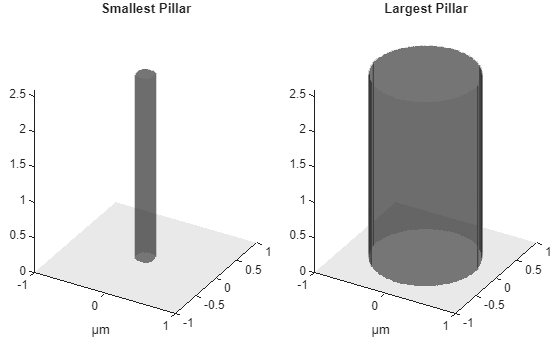

tl = tiledlayout(1, 2, "TileSpacing", "tight", "Padding", "tight");

% Smallest Pillar
[texture_small, profile] = square(n_substrate, n_pillar, n_background, height, min_width, corners, type);
nexttile
title('Smallest Pillar')
plot_texture(texture_small, profile, [pitch, pitch])
axis image
xlabel('μm')

% Largest Pillar
[texture_large, profile] = square(n_substrate, n_pillar, n_background, height, max_width, corners, type);
nexttile
title('Largest Pillar')
plot_texture(texture_large, profile, [pitch, pitch])
axis image
xlabel('μm')

## Simulate the fields inside the smallest and largest pillar

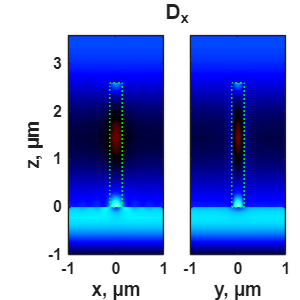

% Simulation settings
center_wavelength = (min_wavelength + max_wavelength) / 2;
fourier_modes = [6, 6];
parm = res0;          % loads the default parameters
parm.sym.x = 0;       % x-direction mirror symmetry plane
parm.sym.y = 0;       % y-direction mirror symmetry plane
parm.sym.pol = 1;     % polarization, TE = 1, TM = -1
parm.res1.champ = 1;  % Uses higher accuracy algorithm for calculating EM fields

x = linspace(-pitch/2, pitch/2, 51);
profile{1}(1) = 1;      % Add space to the 1st and 3rd layer for plotting purposes
profile{1}(3) = 1;

% Smallest Pillar
plot_e_fields(center_wavelength, pitch, texture_small, profile, parm, fourier_modes, x, min_width, height)

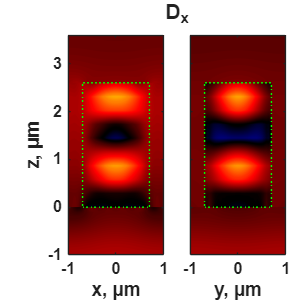

% Largest Pillar
plot_e_fields(center_wavelength, pitch, texture_large, profile, parm, fourier_modes, x, max_width, height)

## Prepare to loop through each pillar size and each wavelength

wavelength = linspace(min_wavelength, max_wavelength, num_wavelengths);
wavelength_lim = [min_wavelength, max_wavelength, num_wavelengths];
width = linspace(min_width, max_width, num_widths);
width_lim = [min_width, max_width, num_widths];

progress_bar_step = 1/num_widths;

trans_data = zeros(num_wavelengths, num_widths, 2);

## Simulate meta-atoms in loop

progress = 0;
fig = uifigure;
fig.Position(3:4) = [460 160];

fig =   Figure with properties:

      Number: []
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [680 458 460 160]
       Units: 'pixels'

  Show all properties


progress_bar = uiprogressdlg(fig, 'Title','Simulating Meta-atoms','Message','Starting parallel pool');

for i = 1:length(height)
    h = height(i);
    for j1 = 1:num_widths
        width_j = width(j1);
        parfor k = 1:num_wavelengths
            [texture, profile] = square(n_substrate, n_pillar, n_background, h, width_j, corners, type);
            [trans, ~] = RCWA_simple(wavelength(k), texture, profile, "fourier_modes", 3);
            trans_data(k,j1,:) = [real(trans) imag(trans)];
        end

        progress = progress + progress_bar_step;
        progress_bar.Value = min(progress, 1);
        progress_bar.Message = sprintf('Progress: % .2f %%', 100*progress);
        drawnow
    end

    note = "Generated with Reticolo, last update 12/2013\n" + ...
        "using Brandon's code SimulateMetaatoms.\n";

    WriteMat(pillar_shape, "MWIR", "micron", "RealImag", ...
        "Material", mat_pillar, "pillar", n_pillar, note_pillar, ...
        "Material", mat_substrate, "substrate", n_substrate, note_substrate, ...
        "Material", mat_background, "background", n_background, note_background,...
        "Param", "wavelength", wavelength_lim, "",...
        "Param", "width", width_lim, "Width of pillar",...
        "Constant", "height", h, "",...
        "Constant", "pitch", pitch, "",...
        "Data", "transmission_bottom_0_0", trans_data, "[Real Imag] of transmitted light",...
        "Notes", note)

    fileProgress = 0;
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


close(fig)
trans_data = complex(trans_data(:, :, 1), trans_data(:, :, 2));

## Plot the phase and transmittance of the meta-atoms

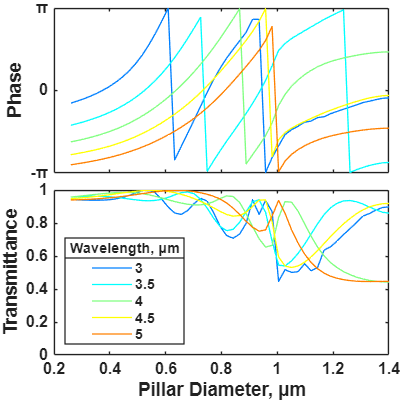

phase = angle(trans_data);
transmittance = abs(trans_data).^2;
colors = jet(num_wavelengths);

fig = figure;
fig.Position(3:4) = [400, 400];
tl = tiledlayout(2, 1, "TileSpacing", "tight", "Padding", "tight");

ax = nexttile;
hold on
for i = 1:num_wavelengths
    plot(width, phase(i, :), Color=colors(i, :))
end
ylim([-pi pi])
ylabel('Phase')
ax.XTickLabel = [];
ax.YTick = [-pi, 0, pi];
ax.YTickLabel = {'-π', '0', 'π'};
format_plot
box on

ax = nexttile;
hold on
for i = 1:num_wavelengths
    plot(width, transmittance(i, :), Color=colors(i, :))
end
ylim([0 1])
xlabel('Pillar Diameter, μm')
ylabel('Transmittance')
% Add legend for the phase plot
lg = legend(ax, string(wavelength), 'Location', 'southwest');
title(lg, 'Wavelength, μm')
format_plot
box on

function [] = plot_e_fields(wavelength, pitch, texture, profile, parameters, fourier_modes, x, width, height)
    aa = res1(wavelength, [pitch, pitch], texture, fourier_modes, 0, 90, parameters);
    [e, z, index] = res3(x, x, aa, profile, [0, 1], parameters);
    
    z = z-1;
    [xx, zz] = meshgrid(x, z);
    index = permute(index, [2, 3, 1]);
    electric_field = permute(e(:, :, :, 1:3), [2, 3, 1, 4]);
    e_max = max(abs(electric_field), [], 'all');
    
    % Electric field in x-direction
    e_field_xz = squeeze(electric_field(:, 26, :, 1));  % xz plane
    e_field_yz = squeeze(electric_field(26, :, :, 1));  % yz plane
    
    % Displacement field in x-direction, normalized by peak value
    d_field_xz = squeeze(index(:, 26, :)).^2 .* e_field_xz;
    d_field_yz = squeeze(index(26, :, :)).^2 .* e_field_yz;
    d_max = max(max(abs(d_field_xz), [], 'all'), max(abs(d_field_yz), [], 'all'));
    d_field_xz = d_field_xz / d_max;
    d_field_yz = d_field_yz / d_max;
    
    % Displacement field phase and amplitude
    d_amp_xz = abs(d_field_xz);
    d_amp_yz = abs(d_field_yz);
    d_phase_xz = angle(d_field_xz);
    d_phase_yz = angle(d_field_yz);
    
    % Create figure window
    fig = figure;
    fig.Position(3:4) = [300 300];
    tl = tiledlayout(1, 2, "TileSpacing", "tight", "Padding", "tight");
    title(tl, 'D_x', FontWeight='bold', FontSize=16)
    ax_xz_ex = nexttile;
    ax_yz_ex = nexttile;
    
    % Display fields inside pillars over time
    phase_input = linspace(0, 2*pi, 30);
    for phase = phase_input
        contourf(ax_xz_ex, xx', zz', d_amp_xz .* cos(d_phase_xz + phase), 100, EdgeColor="none");
        bipolar_colormap(ax_xz_ex)
        rectangle(ax_xz_ex, Position=[-width/2 0 width height], EdgeColor='g', LineStyle=':')
        clim(ax_xz_ex, [-1, 1])
        axis(ax_xz_ex, 'image')
        xlabel(ax_xz_ex, 'x, μm')
        ylabel(ax_xz_ex, 'z, μm')
        format_plot(ax_xz_ex)
        
        contourf(ax_yz_ex, xx', zz', d_amp_yz .* cos(d_phase_yz + phase), 100, EdgeColor="none");
        bipolar_colormap(ax_yz_ex)
        rectangle(ax_yz_ex, Position=[-width/2 0 width height], EdgeColor='g', LineStyle=':')
        clim(ax_yz_ex, [-1, 1])
        axis(ax_yz_ex, 'image')
        xlabel(ax_yz_ex, 'y, μm')
        set(ax_yz_ex, 'YTickLabel', []);
        format_plot(ax_yz_ex)
        pause(0.1)
    end
end